%Object Detection Using YOLO v2 Deep Learning
%Carlos Fonseca
%Jenny Garcia
%Elizabeth Garcia
%CAP 4401 - Digital Imaging Processing
%Professor - Dr. Oge Marques
%Spring 2022 Term
%Due: 4/30/2022

doTraining = false;
if ~doTraining && ~exist('yolov2ResNet50VehicleExample_19b.mat','file')    
    disp('Downloading pretrained detector (98 MB)...');
    pretrainedURL = 'https://www.mathworks.com/supportfiles/vision/data/yolov2ResNet50VehicleExample_19b.mat';
    websave('yolov2ResNet50VehicleExample_19b.mat',pretrainedURL);
end

unzip vehicleDatasetImages.zip
data = load('vehicleDatasetGroundTruth.mat');
vehicleDataset = data.vehicleDataset;

% Display first few rows of the data set.
vehicleDataset(1:4,:)

ans = 4×2 table
              imageFilename                   vehicle     
    _________________________________    _________________

    {'vehicleImages/image_00001.jpg'}    {[220 136 35 28]}
    {'vehicleImages/image_00002.jpg'}    {[175 126 61 45]}
    {'vehicleImages/image_00003.jpg'}    {[108 120 45 33]}
    {'vehicleImages/image_00004.jpg'}    {[124 112 38 36]}


% Add the fullpath to the local vehicle data folder.
vehicleDataset.imageFilename = fullfile(pwd,vehicleDataset.imageFilename);

rng(0);
shuffledIndices = randperm(height(vehicleDataset));
idx = floor(0.6 * length(shuffledIndices) );

trainingIdx = 1:idx;
trainingDataTbl = vehicleDataset(shuffledIndices(trainingIdx),:);

validationIdx = idx+1 : idx + 1 + floor(0.1 * length(shuffledIndices) );
validationDataTbl = vehicleDataset(shuffledIndices(validationIdx),:);

testIdx = validationIdx(end)+1 : length(shuffledIndices);
testDataTbl = vehicleDataset(shuffledIndices(testIdx),:);

imdsTrain = imageDatastore(trainingDataTbl{:,'imageFilename'});
bldsTrain = boxLabelDatastore(trainingDataTbl(:,'vehicle'));

imdsValidation = imageDatastore(validationDataTbl{:,'imageFilename'});
bldsValidation = boxLabelDatastore(validationDataTbl(:,'vehicle'));

imdsTest = imageDatastore(testDataTbl{:,'imageFilename'});
bldsTest = boxLabelDatastore(testDataTbl(:,'vehicle'));

trainingData = combine(imdsTrain,bldsTrain);
validationData = combine(imdsValidation,bldsValidation);
testData = combine(imdsTest,bldsTest);

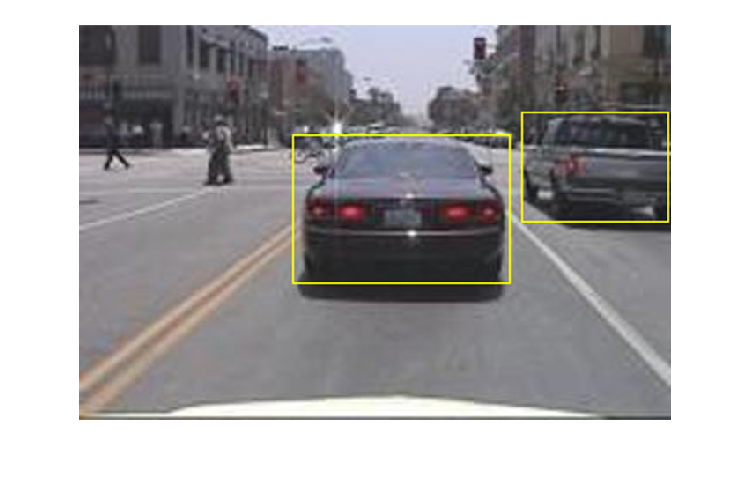

data = read(trainingData);
I = data{1};
bbox = data{2};
annotatedImage = insertShape(I,'Rectangle',bbox);
annotatedImage = imresize(annotatedImage,2);
figure
imshow(annotatedImage)

inputSize = [224 224 3];

numClasses = width(vehicleDataset)-1;

trainingDataForEstimation = transform(trainingData,@(data)preprocessData(data,inputSize));
numAnchors = 7;
[anchorBoxes, meanIoU] = estimateAnchorBoxes(trainingDataForEstimation, numAnchors)

anchorBoxes =    145   126
    91    86
   161   132
    41    34
    67    64
   136   111
    33    23


meanIoU = 0.8651


featureExtractionNetwork = resnet50;

featureLayer = 'activation_40_relu';

lgraph = yolov2Layers(inputSize,numClasses,anchorBoxes,featureExtractionNetwork,featureLayer);

augmentedTrainingData = transform(trainingData,@augmentData);

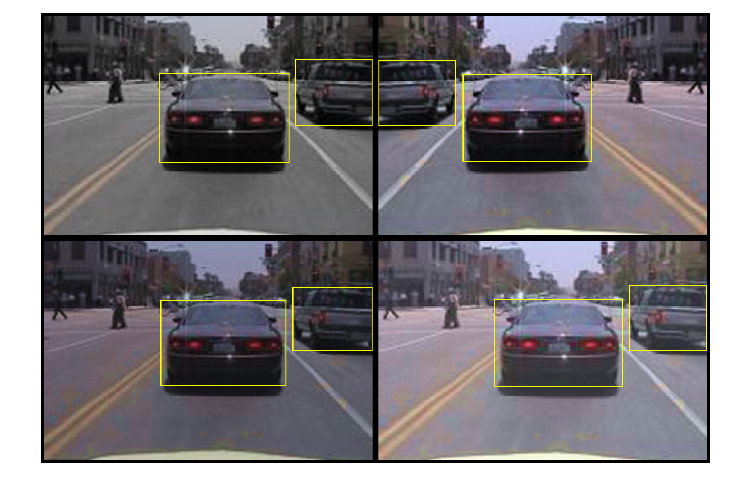

% Visualize the augmented images.
augmentedData = cell(4,1);
for k = 1:4
    data = read(augmentedTrainingData);
    augmentedData{k} = insertShape(data{1},'Rectangle',data{2});
    reset(augmentedTrainingData);
end
figure
montage(augmentedData,'BorderSize',10)

preprocessedTrainingData = transform(augmentedTrainingData,@(data)preprocessData(data,inputSize));
preprocessedValidationData = transform(validationData,@(data)preprocessData(data,inputSize));

data = read(preprocessedTrainingData);

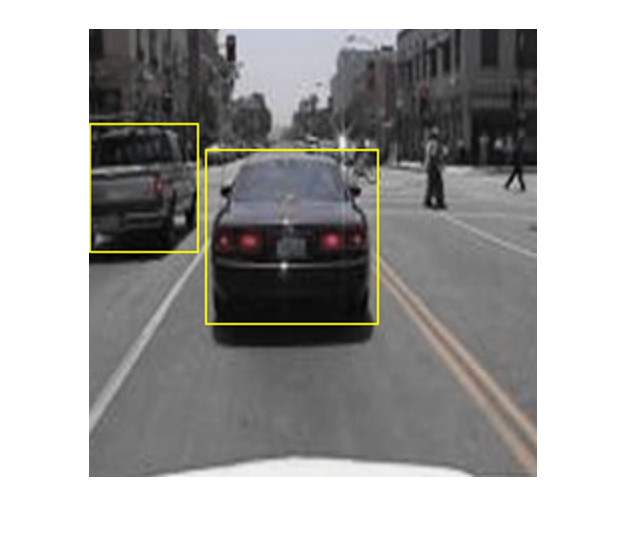

I = data{1};
bbox = data{2};
annotatedImage = insertShape(I,'Rectangle',bbox);
annotatedImage = imresize(annotatedImage,2);
figure
imshow(annotatedImage)

options = trainingOptions('sgdm', ...
        'MiniBatchSize',16, ....
        'InitialLearnRate',1e-3, ...
        'MaxEpochs',20, ... 
        'CheckpointPath',tempdir, ...
        'ValidationData',preprocessedValidationData);

if doTraining       
    % Train the YOLO v2 detector.
    [detector,info] = trainYOLOv2ObjectDetector(preprocessedTrainingData,lgraph,options);
else
    % Load pretrained detector for the example.
    pretrained = load('H:\Digital Imaging Spring 2022\Term Project-CAP4401-CF\yolov2ResNet50VehicleExample_19b.mat');
    detector = pretrained.detector;
end

I = imread('highway.png');
I = imresize(I,inputSize(1:2));
[bboxes,scores] = detect(detector,I);

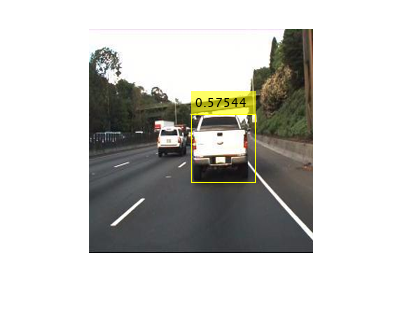

I = insertObjectAnnotation(I,'rectangle',bboxes,scores);
figure
imshow(I)

preprocessedTestData = transform(testData,@(data)preprocessData(data,inputSize));

detectionResults = detect(detector, preprocessedTestData);

[ap,recall,precision] = evaluateDetectionPrecision(detectionResults, preprocessedTestData);

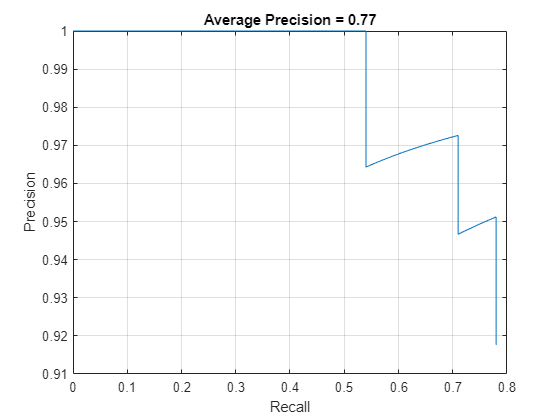

figure
plot(recall,precision)
xlabel('Recall')
ylabel('Precision')
grid on
title(sprintf('Average Precision = %.2f',ap))

function B = augmentData(A)
% Apply random horizontal flipping, and random X/Y scaling. Boxes that get
% scaled outside the bounds are clipped if the overlap is above 0.25. Also,
% jitter image color.

B = cell(size(A));

I = A{1};
sz = size(I);
if numel(sz)==3 && sz(3) == 3
    I = jitterColorHSV(I,...
        'Contrast',0.2,...
        'Hue',0,...
        'Saturation',0.1,...
        'Brightness',0.2);
end

% Randomly flip and scale image.
tform = randomAffine2d('XReflection',true,'Scale',[1 1.1]);
rout = affineOutputView(sz,tform,'BoundsStyle','CenterOutput');
B{1} = imwarp(I,tform,'OutputView',rout);

% Sanitize box data, if needed.
%A{2} = helperSanitizeBoxes(A{2}, sz);

% Apply same transform to boxes.
[B{2},indices] = bboxwarp(A{2},tform,rout,'OverlapThreshold',0.25);
B{3} = A{3}(indices);

% Return original data only when all boxes are removed by warping.
if isempty(indices)
    B = A;
end
end

function data = preprocessData(data,targetSize)
% Resize image and bounding boxes to the targetSize.
scale = targetSize(1:2)./size(data{1},[1 2]);
data{1} = imresize(data{1},targetSize(1:2));
boxEstimate=round(data{2});
boxEstimate(:,1)=max(boxEstimate(:,1),1);
boxEstimate(:,2)=max(boxEstimate(:,2),1);
data{2} = bboxresize(boxEstimate,scale);
end
